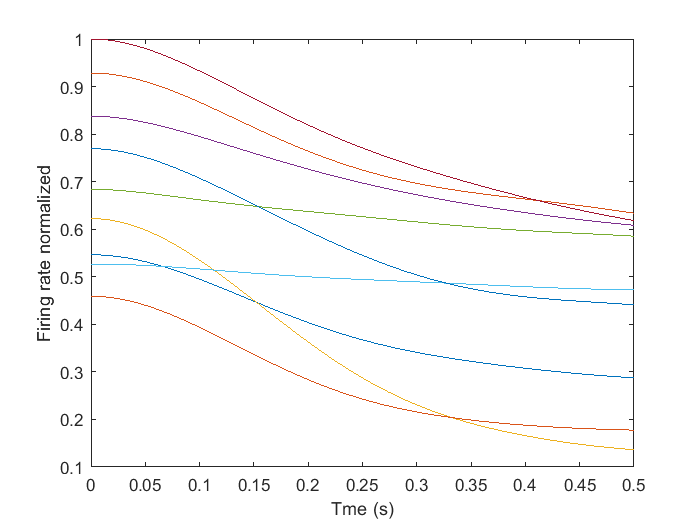

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =     -0.5191  (-0.5207, -0.5174)
       b =      0.6022  (0.5954, 0.6089)
       c =      0.6067  (0.6049, 0.6086)

gof = struct with fields:
           sse: 1.8234
       rsquare: 0.9757
           dfe: 9997
    adjrsquare: 0.9757
          rmse: 0.0135


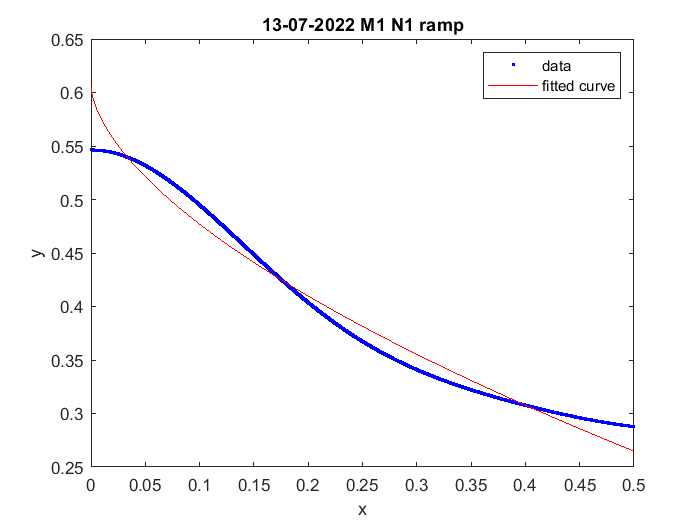

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =     -0.5741  (-0.5758, -0.5723)
       b =      0.5662  (0.5597, 0.5727)
       c =       1.003  (1.001, 1.005)

gof = struct with fields:
           sse: 2.2161
       rsquare: 0.9760
           dfe: 9997
    adjrsquare: 0.9760
          rmse: 0.0149


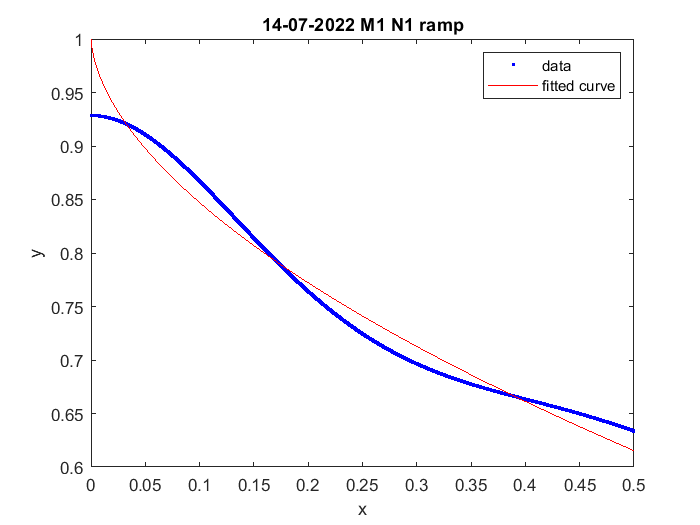

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =      -1.007  (-1.011, -1.004)
       b =      0.6511  (0.6433, 0.659)
       c =      0.7237  (0.72, 0.7273)

gof = struct with fields:
           sse: 8.3644
       rsquare: 0.9703
           dfe: 9997
    adjrsquare: 0.9703
          rmse: 0.0289


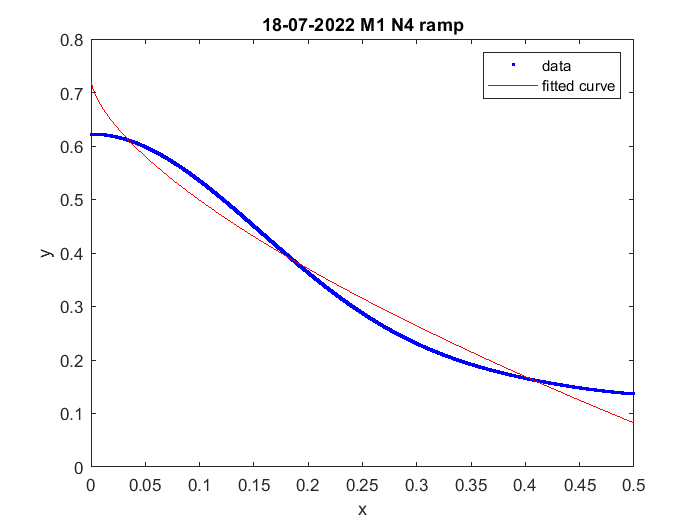

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =     -0.4575  (-0.4583, -0.4566)
       b =      0.6559  (0.6519, 0.6599)
       c =      0.8868  (0.886, 0.8876)

gof = struct with fields:
           sse: 0.4436
       rsquare: 0.9919
           dfe: 9997
    adjrsquare: 0.9919
          rmse: 0.0067


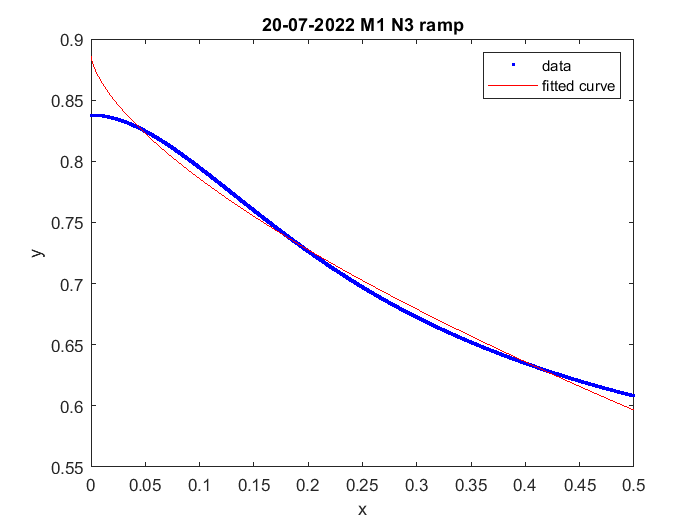

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =     -0.2018  (-0.2019, -0.2018)
       b =      0.7425  (0.7417, 0.7432)
       c =      0.6982  (0.6982, 0.6983)

gof = struct with fields:
           sse: 0.0024
       rsquare: 0.9997
           dfe: 9997
    adjrsquare: 0.9997
          rmse: 4.8686e-04


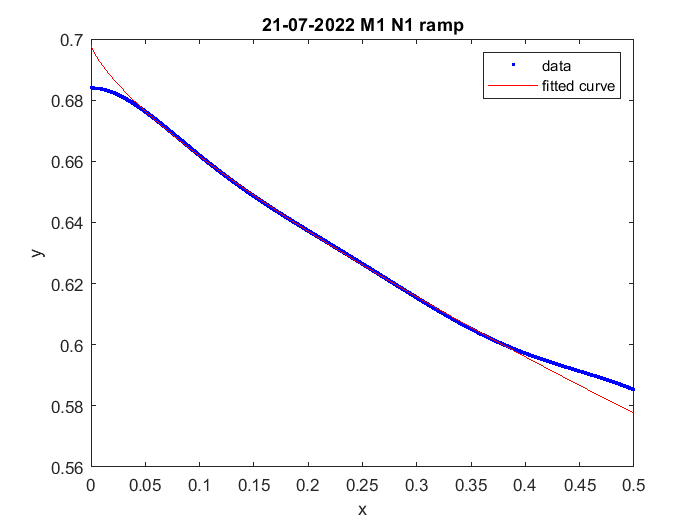

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =     -0.1181  (-0.1181, -0.118)
       b =      0.4469  (0.446, 0.4479)
       c =      0.5579  (0.5578, 0.558)

gof = struct with fields:
           sse: 0.0024
       rsquare: 0.9992
           dfe: 9997
    adjrsquare: 0.9992
          rmse: 4.8666e-04


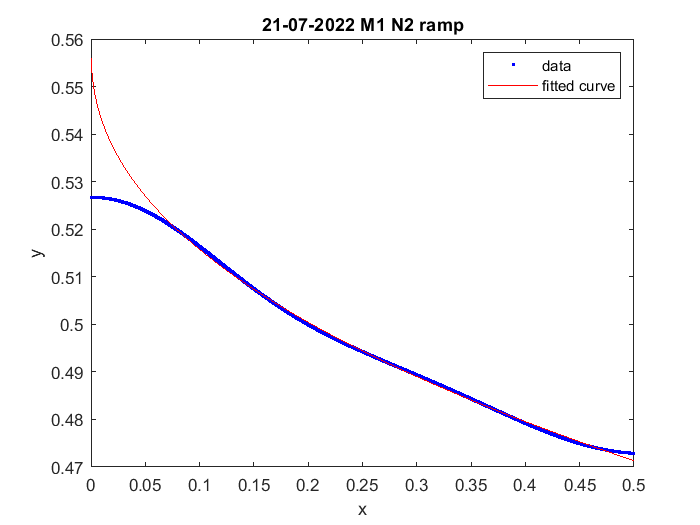

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =      -2.958  (-2.961, -2.956)
       b =     0.08183  (0.08175, 0.08191)
       c =       3.412  (3.409, 3.414)

gof = struct with fields:
           sse: 0.0045
       rsquare: 1.0000
           dfe: 9997
    adjrsquare: 1.0000
          rmse: 6.7439e-04


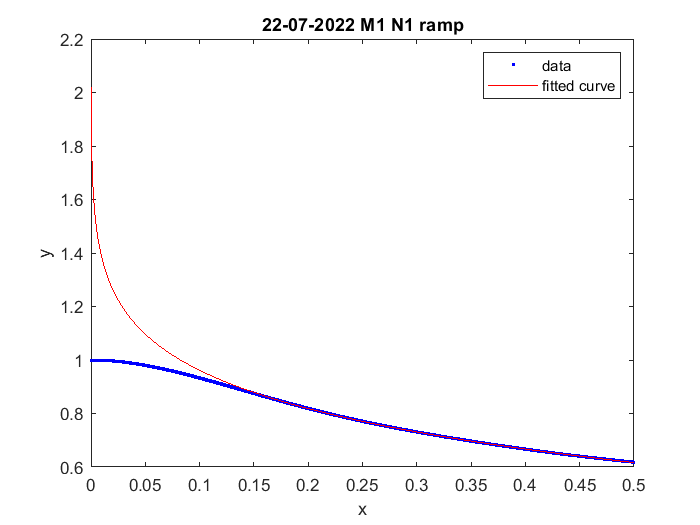

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =     -0.6816  (-0.6841, -0.6791)
       b =      0.6586  (0.6508, 0.6664)
       c =      0.8347  (0.8323, 0.8371)

gof = struct with fields:
           sse: 3.6828
       rsquare: 0.9713
           dfe: 9997
    adjrsquare: 0.9713
          rmse: 0.0192


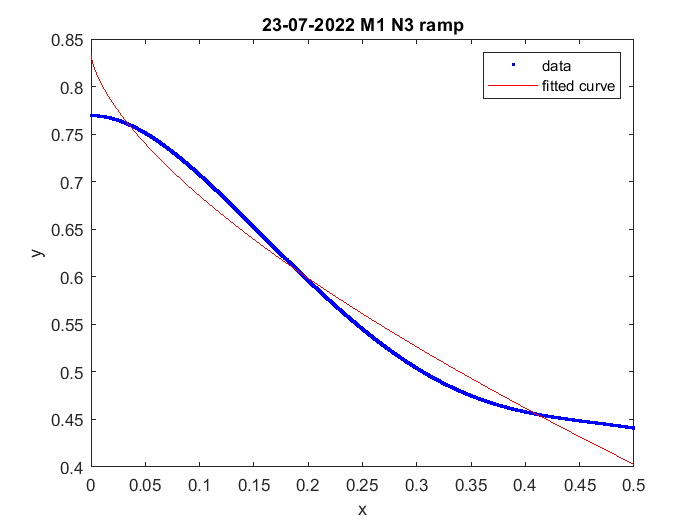

fitresult =      General model Power2:
     fitresult(x) = a*x^b+c
     Coefficients (with 95% confidence bounds):
       a =      -0.576  (-0.5784, -0.5737)
       b =      0.5024  (0.4945, 0.5103)
       c =      0.5508  (0.5475, 0.5542)

gof = struct with fields:
           sse: 3.6890
       rsquare: 0.9605
           dfe: 9997
    adjrsquare: 0.9605
          rmse: 0.0192


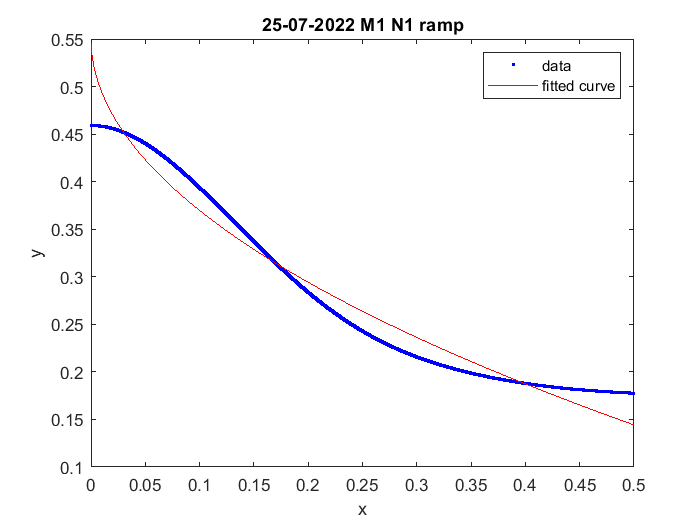

gcfr = T_ramp.descentFR;
fs = 2e4;
t = linspace(0.0001, 0.5, 10000);

maxgcfr = max(gcfr, [], 'all');
gcfr = gcfr./maxgcfr;
figure;
plot(t, gcfr(1:end,:));
xlabel('Tme (s)');
ylabel('Firing rate normalized');

b=nan(1,9);

for i=1:9
    [xData, yData] = prepareCurveData( t, gcfr(i,:) );
    
    % Set up fittype and options.
    ft = fittype( 'power2' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Robust = 'Bisquare';
    % opts.StartPoint = [9397215.94371203 -3.68090399369325];
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts )
    b(i)=fitresult.b;
    figure;
    plot(fitresult, xData, yData);
    title(join([string(T_ramp.date(i)) replace(T_ramp.filename(i), '_',' ')], ' ' ));
    
end